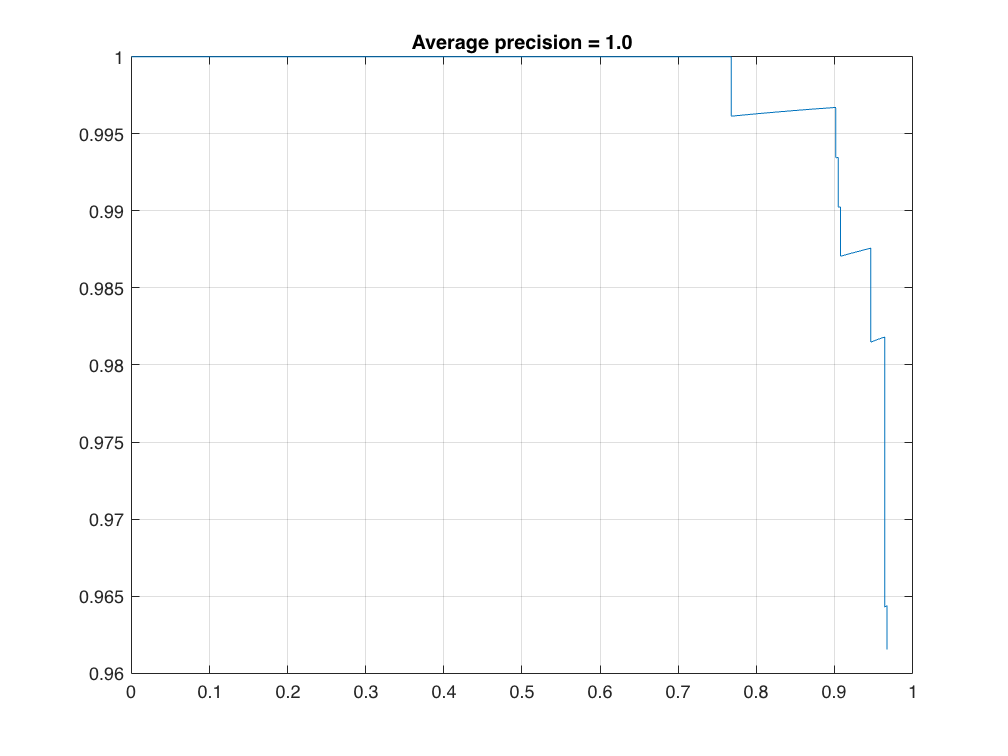


dataDir = fullfile(toolboxdir('vision'), 'visiondata');
trainingData.imageFilename = fullfile(dataDir, trainingData.imageFilename);
% Create an imageDatastore using the files from the table.

imds = imageDatastore(trainingData.imageFilename);
%Create a boxLabelDatastore using the label columns from the table.

blds = boxLabelDatastore(trainingData(:,2:end));
%Load YOLOv2 Detector for Detection

%Load the detector containing the layerGraph for trainining.

vehicleDetector = load('yolov2VehicleDetector.mat');
detector = vehicleDetector.detector;
%Evaluate and Plot the Results

%Run the detector with imageDatastore.

results = detect(detector, imds);

%Evaluate the results against the ground truth data.

[ap, recall, precision] = evaluateDetectionPrecision(results, blds);

%Plot the precision/recall curve.

figure;
plot(recall, precision);
grid on
title(sprintf('Average precision = %.1f', ap))

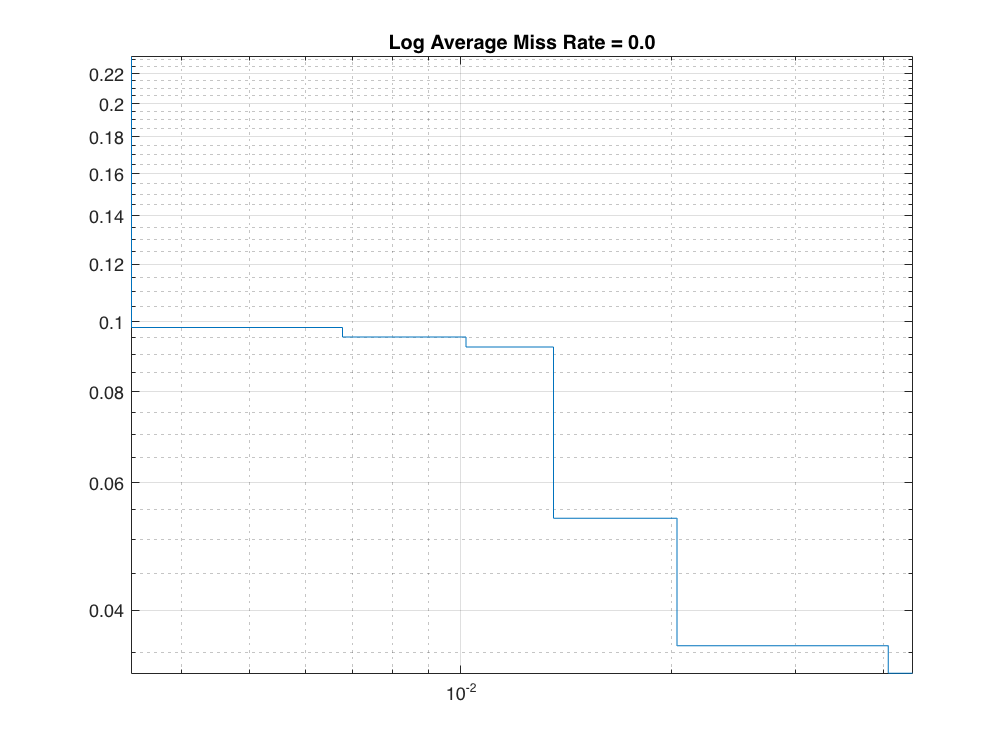


%Evaluating the detection miss rate.

[am, fppi, missRate] = evaluateDetectionMissRate(results, blds);

%Plot the log-miss-rate/FPPI curve.

figure;
loglog(fppi, missRate);
grid on
title(sprintf('Log Average Miss Rate = %.1f', am))